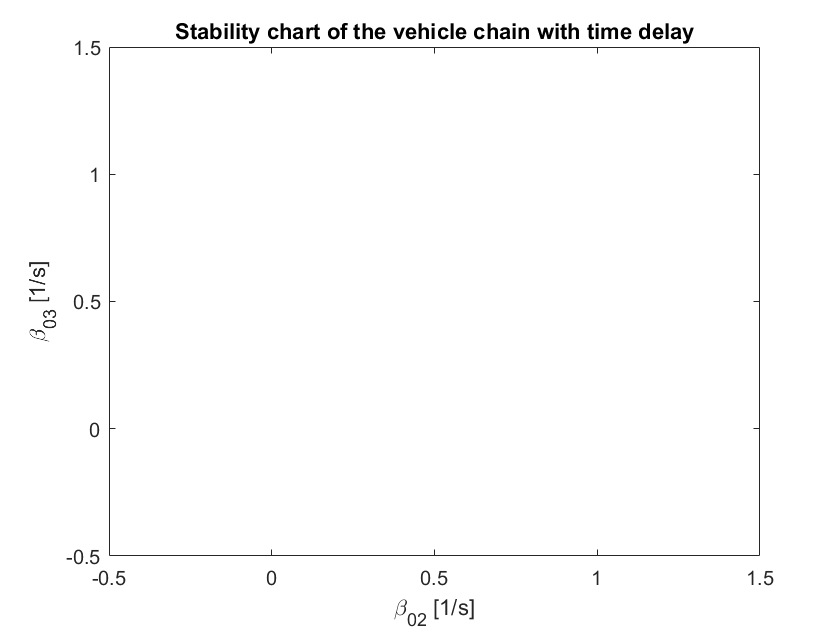

% Code to evaluate link transfer funciton.
% Have to manually fill alpha, beta, sigma, kappa matrix.

clear all; close all;
syms s T om alpha alpha_01 alpha_h...
     beta beta_01 beta_02 beta_03 beta_h... 
     sigma sigma_0 tau...
     kappa_0 kappa_h
 
n = 3; % number of vehicles ahead
kappa_0 = 0.6;
sigma_0 = 0.6;
kappa_h = 0.69;
tau = 1;
alpha_h = 0.2;
beta_h = 0.6;

%           0        1              2         3
ALPHA = [   0     alpha_01         0         0;     %0
            0        0          alpha_h      0;     %1
            0        0             0      alpha_h;  %2
            0        0             0         0];    %3 
        
BETA = [    0     beta_01       beta_02    beta_03;
            0        0          beta_h       0;
            0        0             0       beta_h;
            0        0             0         0];
        
SIGMA = [   0      sigma_0        sigma_0       sigma_0;
            0        0             tau            0;
            0        0             0             tau;
            0        0             0              0];
        
KAPPA = [   0      kappa_0     kappa_0       kappa_0;
            0        0         kappa_h           0;
            0        0             0         kappa_h;
            0        0             0             0];
        

for i = 1:n+1
    for j = 1:n+1
        if j > i
            summation_term = 0;
            for k = i + 1:i+n
                if k > n+1 %to make out of range elements zero.
                    summation_term = 0;
                else
                    summation_term = summation_term +...
                    ((ALPHA(i,k) + BETA(i,k))*s + ALPHA(i,k)*KAPPA(i,k)/(k-i))*exp(-s*SIGMA(i,k));                    
                end                
            end
            T(i,j) = ((s*BETA(i,j) + ALPHA(i,j)*KAPPA(i,j)/(j-i))*exp(-s*SIGMA(i,j)))/...
                 (s^2 + summation_term);
        else
            T(i,j) = 0;
        end
    end
end

T = simplify(T);
% have to calculate the expression of Head_to_tail TF analytically
head_to_tail_TF = T(1,2)*T(2,3)*T(3,4) + T(1,3)*T(3,4) + T(1,4);
head_to_tail_TF = simplify(subs(head_to_tail_TF,s,1i*om));



% % Plant stability
% Deno = simplify((alpha_01*kappa_0 + alpha_01*s + beta_01*s + beta_02*s + beta_03*s + s^2*exp(s*sigma_0)));
% Deno_jw  = simplify((rewrite(subs(Deno,s,1i*om),'sin')));
% assume([alpha_01,beta_01,beta_02,beta_03,sigma_0,tau,om,kappa_0],'real');
% real_Deno_jw = real(Deno_jw);
% real_Deno_jw = subs(real_Deno_jw,alpha_01,alpha);
% img_Deno_jw = imag(Deno_jw);
% img_Deno_jw = subs(img_Deno_jw,[alpha_01,beta_01,beta_02,beta_03],[alpha,beta/3,beta/3,beta/3]);
% assume([alpha_01,beta_01,beta_02,beta_03,sigma_0,tau,om,kappa_0],'clear');
% plant_stability_plot(alpha,beta,real_Deno_jw,img_Deno_jw);

%Brute force (beta_03,beta_02) plane
brute_force(sigma_0,tau,kappa_0,kappa_h,alpha_h,beta_h);

function plant_stability_plot(alpha,beta,real_Deno_jw,img_Deno_jw)
    
    solu = solve([real_Deno_jw==0,img_Deno_jw==0],[alpha,beta],"MaxDegree",3);
    
    alphamin = -1;
    alphamax = 4;
    betamin = -2;
    betamax = 3;
    
    ommin = 0;
    ommax = 2*pi;
    dom = 0.01;
    om=ommin:dom:ommax;
    
    alpha01=@(beta)0*beta;
    
    figure(1); clf; hold on; box on;
    for ksolu=1:length(solu.beta)
        % evaluate the string stability limit for different values of omega
        betastring=eval(solu.beta(ksolu));      %Evaluating alphas and betas at at the om
        alphastring=eval(solu.alpha(ksolu));
        % remove complex values
        betastring(imag(betastring)~=0)=nan;
        alphastring(imag(alphastring)~=0)=nan;
        % remove possible asymptotes
        betastring(betastring>betamax | betastring<betamin)=nan;
        % plot omega>0 string stability boundaries
        plot(betastring,alphastring,'b');
    end

    plot([betamin,betamax],alpha01([betamin,betamax]),'k');
    axis([betamin betamax alphamin alphamax]);
    xlabel('\beta_{01}+\beta_{02}+\beta_{03} [1/s]');
    ylabel('\alpha [1/s]');
    title('Plant stability chart of the vehicle chain with time delay');
end

function brute_force(sigma_0,tau,kappa_0,kappa_h,alpha_h,beta_h)
    
    % range of parameters
    alpha_01 = 0.4;
    beta_01 = 0.2;
    
    beta_02min=-0.5;    
    beta_02max=1.5;     
    beta_03min=-0.5;	
    beta_03max=1.5;     
    step=200;

    
    % range of frequencies
    ommin=0;
    ommax=2*pi;
    dom=0.05;
        
    % vectors of parameter and frequency values
    beta_03_v=linspace(beta_03min,beta_03max,step+1);
    beta_02_v=linspace(beta_02min,beta_02max,step+1);
    om_v=ommin:dom:ommax;
    
    % matrix of parameter, frequency and transfer function values
    [beta_02,beta_03,om] = meshgrid(beta_02_v,beta_03_v,om_v);
    
    T =(exp(-om.*tau.*2i).*...
       (beta_03.*om.^5.*exp(om.*tau.*2i).*1i - beta_01.*beta_h.^2.*om.^3.*1i + beta_02.*beta_h.*om.^4.*exp(om.*tau.*1i) + alpha_01.*alpha_h.^2.*kappa_0.*kappa_h.^2 - alpha_01.*beta_h.^2.*kappa_0.*om.^2 + alpha_h.^2.*beta_01.*kappa_h.^2.*om.*1i - alpha_h.*beta_02.*kappa_h.*om.^3.*exp(om.*tau.*1i).*1i - 2.*alpha_h.*beta_01.*beta_h.*kappa_h.*om.^2 + alpha_01.*alpha_h.*beta_h.*kappa_0.*kappa_h.*om.*2i))./...
       (om.^4.*(alpha_01.*kappa_0 + alpha_01.*om.*1i + beta_01.*om.*1i + beta_02.*om.*1i + beta_03.*om.*1i - om.^2.*exp(om.*sigma_0.*1i)));
    M=abs(T);


    % same with for loops
    stab = zeros(length(beta_03_v),length(beta_02_v));
    for kb=1:length(beta_02_v)
        for ka=1:length(beta_03_v)
        stab(ka,kb)=all(squeeze(M(ka,kb,2:end))<1);
        end
    end
    
    %% Plot stability chart
    figure(1); clf; hold on; box on;
    contourf(beta_02(:,:,1),beta_03(:,:,1),stab,[1 1],'k')
    colormap gray
    xlabel('\beta_{02} [1/s]')
    ylabel('\beta_{03} [1/s]')
    axis([beta_02min beta_02max beta_03min beta_03max]);
    title('Stability chart of the vehicle chain with time delay');
    
%     %% Plot frequency response
%     figure(1); [beta0,alpha0]=ginput(1);    % (beta,alpha) by clicking on stability chart
%     % beta0=0.4; alpha0=0.2;                % or given (beta,alpha)
%     
%     % get closest parameter values to the selected ones
%     beta0=interp1(beta_02_v,beta_02_v,beta0,'nearest');
%     alpha0=interp1(beta_03_v,beta_03_v,alpha0,'nearest');
%     % get corresponding frequency response
%     M_v=squeeze(M(beta_03_v==alpha0,beta_02_v==beta0,:));
%     
%     figure(2); clf; hold on; box on;
%     title(['\beta=',num2str(beta0),'   \alpha=',num2str(alpha0)]);
%     plot(om_v,M_v);
%     plot([ommin ommax],[1 1],'k--');
%     xlabel('\omega [rad/s]');
%     ylabel('|T(j\omega)|');
%     xlim([ommin ommax]);
%     title('Frequency response of the vehicle chain with time delay');
    
end